# **TRATAMIENTO DIGITAL DE IMAGENES**

#### **Máster Universitario en Visión Artificial (URJC). **

## **Autor: Vicente Gilabert Mañó**

**Práctica 2: Segmentación basada en regiones y morfología matemática****.**

**2.A.- Desarrollar un programa que calcule el mapa de disparidad entre un par estéreo a su elección, mediante la técnica de ajuste de bloques, con un tamaño de bloque que se elija a criterio del usuario (11x11 es un tamaño típico) y que represente el resultado como una imagen en escala de grises. Comente los resultados obtenidos.**

Para la realización de la práctica, se han desarrollado las siguientes funciones:

- **getDisparity(img_ref,img_comp,N,limit,form):** con esta función obtenemos el mapa de disparidad de dos imágenes (*img_ref *y* img_comp*). Este proceso es realizado mediante la técnica BlockMatching. Donde *N* es el tamaño del bloque (*NxN*), *limit* es el rango que se va a desplazar el bloque por la otra imagen y form es la escuación para el cálculo de la distancia (ssd o sad).

- **blockComparison(img_ref,img_comp,N,act_x,act_y,limit,form): **con esta función realizamos el desplazamiento y comparación del bloque de la *img_ref* con la *img_comp*. Donde *N* es el tamaño del bloque (*NxN*), *act_x (x_ini *y* x_end)* es la posición x del bloque, *act_y (y_ini *y* y_end)* es la posición y del bloque, *limit* es el rango que se va a desplazar el bloque por la otra imagen y form es la formula para el cálculo de la distancia (ssd o sad).

La práctica se divide en tres secciones diferentes:

- (1.1) Obtención del mapa de disparidad para un ejemplo de imágenes.

- (1.2) Obtención del mapa de disparidad para un ejemplo de imágenes.

- (2) Se comentan unas concluciones de la práctica.

## (1.1) Ejemplo 1 para el cálculo del mapa de disparidad.

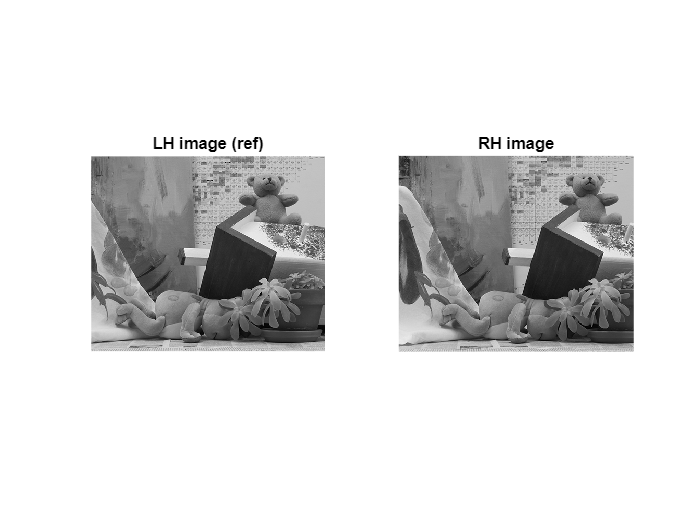

%% Clear space and load images.
clear; clc; close all;

% Load and get size of image. Convert to gray if is color image.
img_RH = double(rgb2gray(imread('images/img_RH1.png')));
img_LH = double(rgb2gray(imread('images/img_LH1.png'))); %reference imagen

% Plot original images.
figure
subplot(1,2,1)
imshow(uint8(img_LH))
title('LH image (ref)')
subplot(1,2,2)
imshow(uint8(img_RH))
title('RH image')

N = 11; %block size (NxN)
limit = 70; % movement of block (x to x+limit).

tic
disp = getDisparity(img_LH,img_RH,N,limit,'ssd');
toc

Elapsed time is 28.527115 seconds.


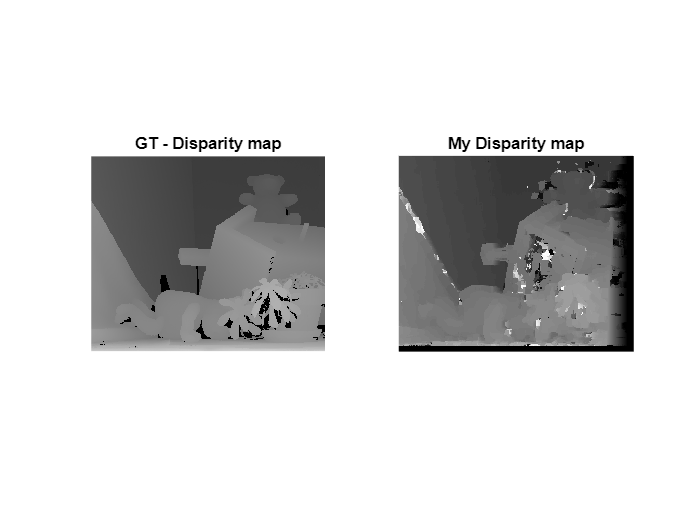

% Plot result and original groundtruth disparity map.
figure
subplot(1,2,1)
imshow(uint8(imread("images/disp_1.png")))
title('GT - Disparity map')
subplot(1,2,2)
imshow(uint8(rescale(disp,0,255)))
title('My Disparity map')

## (1.2) Ejemplo 2 para el cálculo del mapa de disparidad.

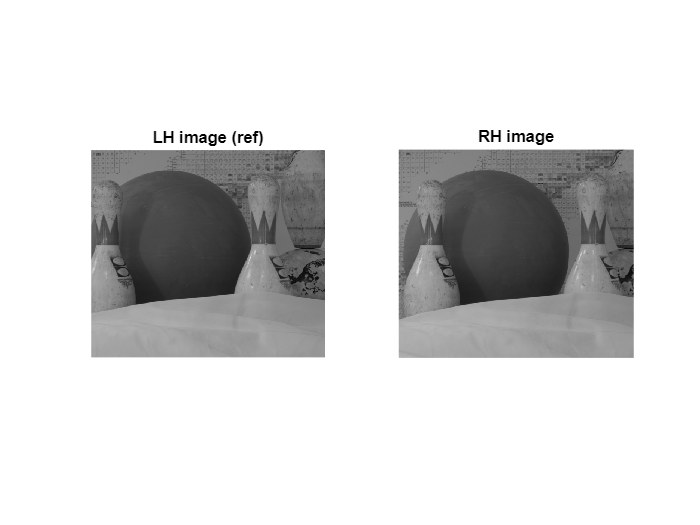

% Clear space and load images.
clear; clc; close all;

% Load and get size of image. Convert to gray if is color image.
img_RH = double(rgb2gray(imread('images/img_RH2.png')));
img_LH = double(rgb2gray(imread('images/img_LH2.png'))); %reference imagen

% Plot original images.
figure
subplot(1,2,1)
imshow(uint8(img_LH))
title('LH image (ref)')
subplot(1,2,2)
imshow(uint8(img_RH))
title('RH image')


N = 11; %block size (NxN)
limit = 70; % movement of block (x to x+limit).

tic
disp = getDisparity(img_LH,img_RH,N,limit,'ssd');
toc

Elapsed time is 65.359035 seconds.


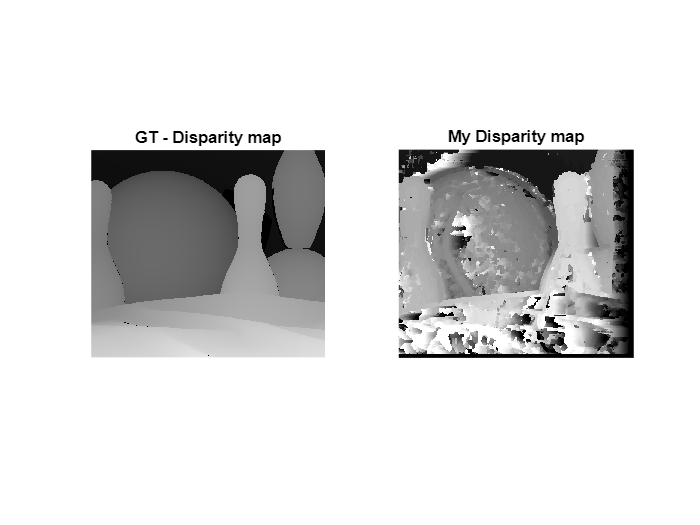


% Plot result and original groundtruth disparity map.
figure
subplot(1,2,1)
imshow(uint8(imread("images/disp_2.png")))
title('GT - Disparity map')
subplot(1,2,2)
imshow(uint8(rescale(disp,0,255)))
title('My Disparity map')

## **(2) CONCLUSIONES**

- Se han implementado las funciones necesarias para realizar el mapa de dispersión de un par estéreo de imágenes. El resultado se puede aproximar a un mapa de profundidad, donde los colores más oscuros están más alejados, mientras que los más claros están mas cerca. La técnica que se utiliza es la llamada ***Block Matching***. Esta técnica consiste en dado un bloque de la *img_ref*, encontrar el bloque mas parecido en la *img_comp* desplazando el eje x.

- Se ha probado dos diferentes fórmulas para el cálculo de la disparidad entre bloques:

SAD

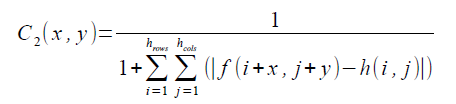

SSD

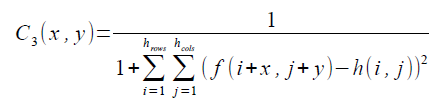

- Los resultados obtenidos son similares, pero se observa un mejor resultado con SSD, pero una mayor rapidez con SAD.